# Shallow shell structure with geometric nonlinearities

Finite element model used in the following reference:

Jain, S., & Tiso, P. (2018). Simulation-free hyper-reduction for geometrically nonlinear structural dynamics: a quadratic manifold lifting approach. *Journal of Computational and Nonlinear Dynamics*, *13*(7), 071003. [https://doi.org/10.1115/1.4040021](https://doi.org/10.1115/1.4040021)

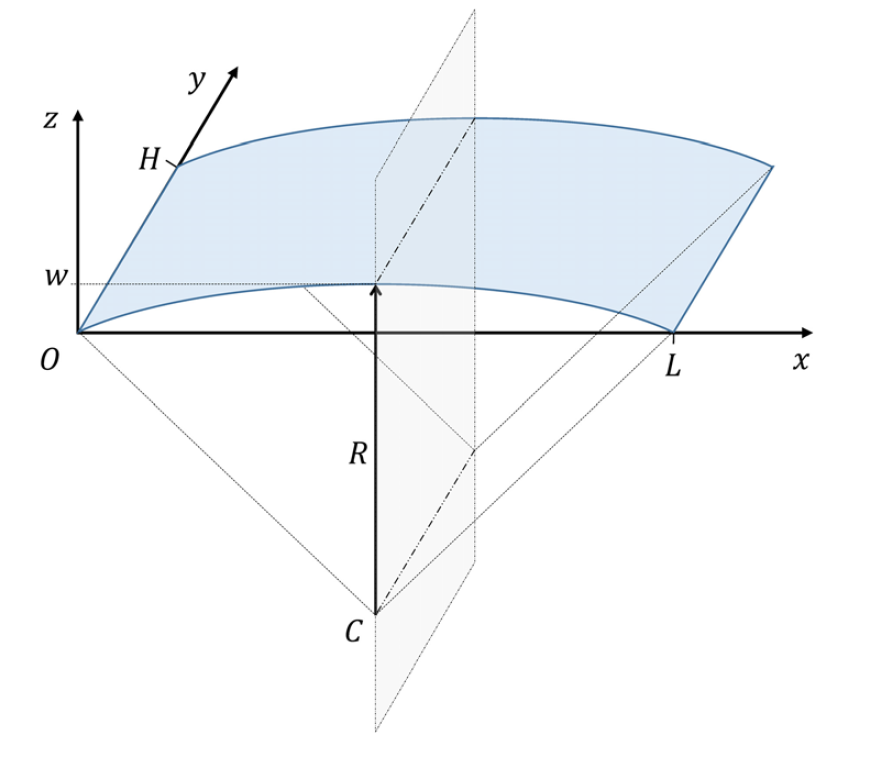

Here we take density $\rho$ and Young's modulus $E$ as system parameters and compute the sensitvity of SSM with respect to them. Here we take Rayleigh damping below


$$C=\alpha M+\beta K$$


the coefficients $\alpha$ and $\beta$ are choosen in the following two ways

- they are choosen such that the damping ratio of the first two modes are equal to 0.004 at nominal values of $\rho$ and $E$. In this case, both $\alpha$ and $\beta$ are constants;

- they are choosen such that the damping ratio of the first mode is fixed as a given value. In this case, $\alpha$ and $\beta$ can be $\omega$ dependent.

### Create dynamical model

clear all;
ngrids = 3;
E   = 70e9;
rho = 2700; Om = 148;
zeta = 0.02;
[M,K,fnl,fext,DM,DK,dfnl2,dfnl3,dfext,outdof] = build_model_semi(ngrids,E,rho);

Building FE model
Loaded matrices and tensors from storage


lamd = eigs(K,M,1,'smallestabs'); 
om = sqrt(lamd);
al = zeta*om; 
be = zeta/om;
C  = al*M+be*K;
DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl_semi',fnl);
set(DS.Options,'Emax',3,'Nmax',6)
set(DS,'DM',DM,'DK',DK);
set(DS,'al',@(x) zeta*x,'be',@(x) zeta/x,'dal',@(x) zeta,'dbe',@(x) -zeta/x^2);
set(DS,'Dfnl2_semi',dfnl2,'Dfnl3_semi',dfnl3);
set(DS,'fext',fext,'Omega',Om,'dfext',dfext);
[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000000e-02
modal damping ratio for 2 mode is 2.609556e-02
modal damping ratio for 3 mode is 3.158987e-02
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 6 eigenvalues are given as 
   1.0e+02 *

  -0.0295 + 1.4743i
  -0.0295 - 1.4743i
  -0.0825 + 3.1587i
  -0.0825 - 3.1587i
  -0.1305 + 4.1298i
  -0.1305 - 4.1298i



### SSM computation - explicit computation

S = SSM(DS);
set(S.Options,'solver','backslash');
resonant_modes = [1 2]; % choose master spectral subspace
S.choose_E(resonant_modes);

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     1
     0     2
     1     3
     3     0
     0     3

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0825 + 3.1587i
  -0.0825 + 3.1587i
  -0.0825 - 3.1587i
  -0.0825 - 3.1587i
  -0.1305 + 4.1298i
  -0.1305 - 4.1298i

sigma_out = 4
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     1     2

These are in resonance with the follwing eigenvalues of the master subspace
   1.0e+02 *

  -0.0295 + 1.4743i
  -0.0295 - 1.4743i

sigma_in = 4


order = 3; % SSM expansion order
[We,Re] = S.explicit_whisker();


 second order explict solution 


### SSM computation - via SSMTool parameterization

Building FE model


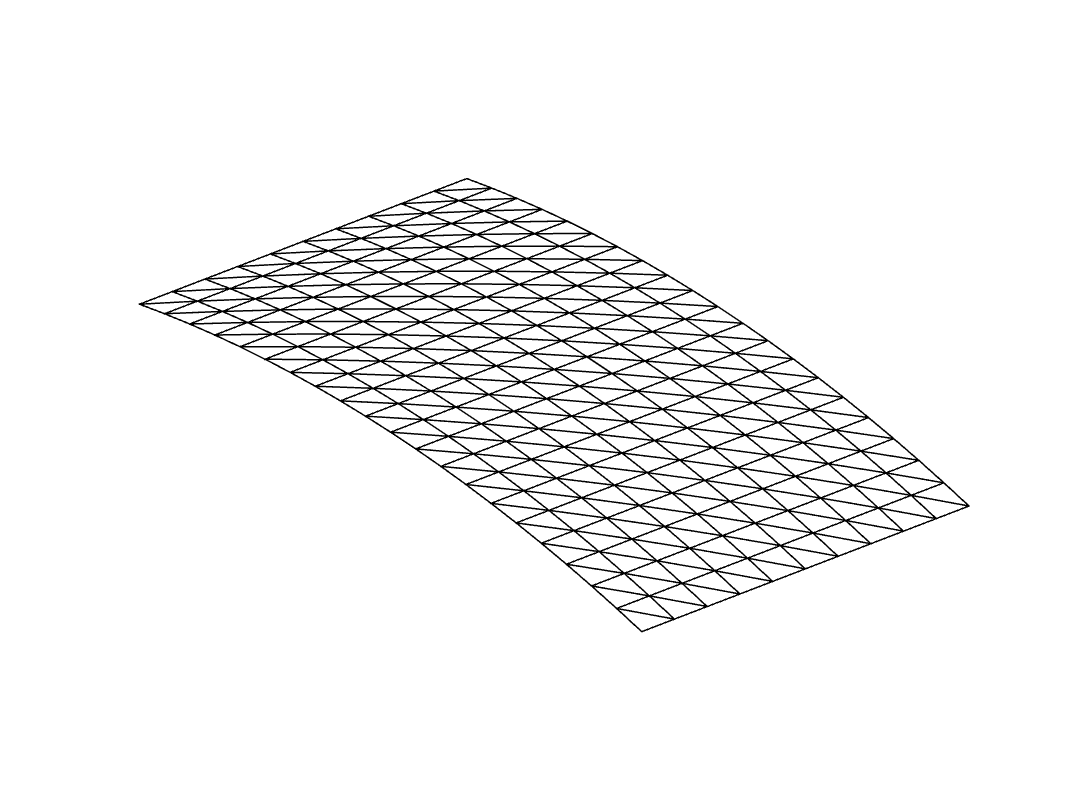

Getting nonlinearity coefficients
Loaded matrices and tensors from storage
With fixed damping ratio for the first mode
Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000000e-02
modal damping ratio for 2 mode is 2.609556e-02
modal damping ratio for 3 mode is 3.158987e-02
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 6 eigenvalues are given as 
   1.0e+02 *

  -0.0295 + 1.4743i
  -0.0295 - 1.4743i
  -0.0825 + 3.1587i
  -0.0825 - 3.1587i
  -0.1305 + 4.1298i
  -0.1305 - 4.1298i

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     3     1
     0     2
     0     3
     1     3
     2     0
     3     0
     3     1
     0     2
     0     3
     1     3

These are in resonance with th

[W_0,R_0,W_1,R_1] = ssmtool_comp(ngrids,E,rho,'type2',Om);

### SSM senstivity computation

[DW,DR] = S.explicit_senstivity_whisker(We,Re);


 damping ratio is 2.000000e-02


DW10 = DW.DW10; DW20 = DW.DW20; DW11 = DW.DW11;
DW30 = DW.DW30; DW21 = DW.DW21; Dx0 = DW.Dx0;
Dlamd = DR.Dlamd; Dr21 = DR.Dr21;
Dom = DR.Dom; Dpsi = DR.Dpsi; Dftilde = DR.Dftilde;

### SSM computation - $\gamma$ via adjoint method

tic
dr21_adj = S.adjoint_sentivity(We.W20,We.W11,We.W30,We.W21,Re.r21);


 damping ratio is 2.000000e-02


toc

Elapsed time is 468.990965 seconds.


### Comparison of SSM results 

#### Explicit solution and SSMTool solution

fprintf('\n difference in terms of W10 \n')


 difference in terms of W10 


norm(We.W10-full(W_0(1).coeffs(:,2)))/norm(We.W10)

ans = 8.7908e-17

fprintf('\n difference in terms of W20 \n')


 difference in terms of W20 


norm(We.W20-full(W_0(2).coeffs(:,3)))/norm(We.W20)

ans = 2.2409e-13

fprintf('\n difference in terms of W11 \n')


 difference in terms of W11 


norm(We.W11-full(W_0(2).coeffs(:,2)))/norm(We.W11)

ans = 3.1885e-12

fprintf('\n difference in terms of W30 \n')


 difference in terms of W30 


norm(We.W30-full(W_0(3).coeffs(:,4)))/norm(We.W30)

ans = 1.8792e-12

fprintf('\n difference in terms of W21 \n')


 difference in terms of W21 


norm(We.W21-full(W_0(3).coeffs(:,3)))/norm(We.W21)

ans = 2.1462e-10

fprintf('\n difference in terms of x0 \n')


 difference in terms of x0 


norm(We.x0-W_1(2).W.coeffs)/norm(We.x0)

ans = 1.0763e-11

fprintf('\n difference in terms of gamma \n')


 difference in terms of gamma 


abs(Re.r21-full(R_0(3).coeffs(1,2)))/abs(Re.r21)

ans = 1.0770e-13

fprintf('\n difference in terms of ftilde \n')


 difference in terms of ftilde 


abs(Re.ftilde-R_1(2).R.coeffs(1))/abs(Re.ftilde)

ans = 5.5170e-14

Note: if solver='lsqminnorm', difference can be much more significant

### Compare results - sensitivity of SSM. (Explicit vs central finite difference)

#### Derivatives w.r.t $\rho$

% compute perturbed SSMs
drho = 0.001*rho;
ssm_rhop = comp_ssm(ngrids,E,rho+drho,Om,'type2');

Building FE model
Loaded matrices and tensors from storage
With fixed damping ratio for the first mode
Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000000e-02
modal damping ratio for 2 mode is 2.609556e-02
modal damping ratio for 3 mode is 3.158987e-02
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 6 eigenvalues are given as 
   1.0e+02 *

  -0.0295 + 1.4735i
  -0.0295 - 1.4735i
  -0.0824 + 3.1572i
  -0.0824 - 3.1572i
  -0.1305 + 4.1277i
  -0.1305 - 4.1277i

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     3     1
     0     2
     0     3
     1     3
     2     0
     3     0
     3     1
     0     2
     0     3
     1     3

These are in resonance with the follwing eigen

ssm_rhom = comp_ssm(ngrids,E,rho-drho,Om,'type2');

Building FE model
Loaded matrices and tensors from storage
With fixed damping ratio for the first mode
Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000000e-02
modal damping ratio for 2 mode is 2.609556e-02
modal damping ratio for 3 mode is 3.158987e-02
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 6 eigenvalues are given as 
   1.0e+02 *

  -0.0295 + 1.4750i
  -0.0295 - 1.4750i
  -0.0825 + 3.1603i
  -0.0825 - 3.1603i
  -0.1306 + 4.1319i
  -0.1306 - 4.1319i

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     3     1
     0     2
     0     3
     1     3
     2     0
     3     0
     3     1
     0     2
     0     3
     1     3

These are in resonance with the follwing eigen

% Calculate derivatives
dr21_drho = (ssm_rhop.r21-ssm_rhom.r21)/(2*drho);
% compute relative or absolute errors and print them 
fprintf('relative error for dr21_drho is %d\n', norm(Dr21(1)-dr21_drho)/norm(Dr21(1)));

relative error for dr21_drho is 1.458199e-06


#### Derivatives w.r.t $E$

% computation of peturbed SSMs
dE = 1e-10*E; 
ssm_Ep = comp_ssm(ngrids,E+dE,rho,Om,'type2');

Building FE model
Loaded matrices and tensors from storage
With fixed damping ratio for the first mode
Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000000e-02
modal damping ratio for 2 mode is 2.609556e-02
modal damping ratio for 3 mode is 3.158987e-02
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 6 eigenvalues are given as 
   1.0e+02 *

  -0.0295 + 1.4743i
  -0.0295 - 1.4743i
  -0.0825 + 3.1587i
  -0.0825 - 3.1587i
  -0.1305 + 4.1298i
  -0.1305 - 4.1298i

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     3     1
     0     2
     0     3
     1     3
     2     0
     3     0
     3     1
     0     2
     0     3
     1     3

These are in resonance with the follwing eigen

ssm_Em = comp_ssm(ngrids,E-dE,rho,Om,'type2');

Building FE model
Loaded matrices and tensors from storage
With fixed damping ratio for the first mode
Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000000e-02
modal damping ratio for 2 mode is 2.609556e-02
modal damping ratio for 3 mode is 3.158987e-02
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 6 eigenvalues are given as 
   1.0e+02 *

  -0.0295 + 1.4743i
  -0.0295 - 1.4743i
  -0.0825 + 3.1587i
  -0.0825 - 3.1587i
  -0.1305 + 4.1298i
  -0.1305 - 4.1298i

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     3     1
     0     2
     0     3
     1     3
     2     0
     3     0
     3     1
     0     2
     0     3
     1     3

These are in resonance with the follwing eigen

% calculate derivatives
dw10_dE = (ssm_Ep.W10-ssm_Em.W10)/(2*dE);
dw20_dE = (ssm_Ep.W20-ssm_Em.W20)/(2*dE);
dw11_dE = (ssm_Ep.W11-ssm_Em.W11)/(2*dE);
dw30_dE = (ssm_Ep.W30-ssm_Em.W30)/(2*dE);
dw21_dE = (ssm_Ep.W21-ssm_Em.W21)/(2*dE);
dlam_dE = (ssm_Ep.lamd-ssm_Em.lamd)/(2*dE);
dr21_dE = (ssm_Ep.r21-ssm_Em.r21)/(2*dE);
dx0_dE  = (ssm_Ep.x0-ssm_Em.x0)/(2*dE);
dftilde_dE = (ssm_Ep.ftilde-ssm_Em.ftilde)/(2*dE);

% compute relative or absolute errors and print them
fprintf('absolute error for dw10_dE is %d\n', norm(DW10(:,2)-dw10_dE)); 

absolute error for dw10_dE is 2.164832e-11


fprintf('absolute error for dw20_dE is %d\n', norm(DW20(:,2)-dw20_dE)); 

absolute error for dw20_dE is 3.421718e-07


fprintf('absolute error for dw11_dE is %d\n', norm(DW11(:,2)-dw11_dE)); 

absolute error for dw11_dE is 2.450859e-09


fprintf('absolute error for dw30_dE is %d\n', norm(DW30(:,2)-dw30_dE)); 

absolute error for dw30_dE is 2.462491e-06


fprintf('absolute error for dw21_dE is %d\n', norm(DW21(:,2)-dw21_dE)); 

absolute error for dw21_dE is 1.318579e-06


fprintf('absolute error for dlamd_dE is %d\n', norm(Dlamd(2)-dlam_dE)); 

absolute error for dlamd_dE is 3.126702e-12


fprintf('absolute error for dr21_dE is %d\n', norm(Dr21(2)-dr21_dE));

absolute error for dr21_dE is 4.442469e-07


fprintf('absolute error for dx0_dE is %d\n', norm(Dx0(:,2)-dx0_dE));

absolute error for dx0_dE is 1.247772e-13


fprintf('absolute error for dftilde_dE is %d\n', norm(Dftilde(2)-dftilde_dE));

absolute error for dftilde_dE is 8.931940e-17
